===============================================================================

# Pràctica 8. Derivació Numèrica

`Document preparat per Mª Àngela Grau Gotés (prof. responsable CN)`

## 1. Introducció

A més a més dels exercicis d'aquest script teniu disponibles exercicis en el document Guia-Lab8.pdf i en el document CN_full7.pdf, els podeu trobar en el campus virtual. 

### MATLAB®  -  Derivació numèrica

Use the `diff` function to approximate partial derivatives with the syntax `Y = diff(f)/h`, where `f` is a vector of function values evaluated over some domain, `X`, and `h` is an appropriate step size.

For example, the first derivative of `sin(x)` with respect to `x` is `cos(x)`, and the second derivative with respect to `x` is `-sin(x)`. You can use `diff` to approximate these derivatives.

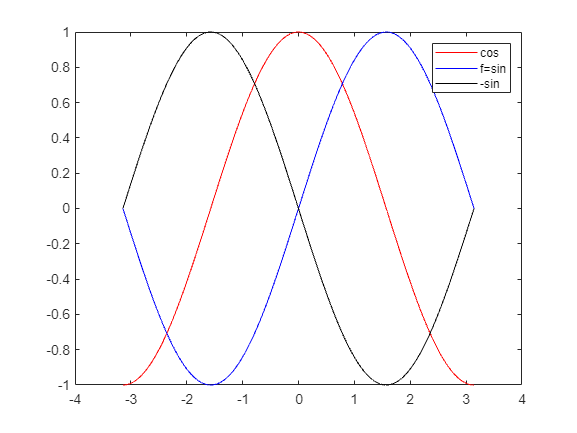

h = 0.001;       % step size
X = -pi:h:pi;    % domain
f = sin(X);      % range
Y = diff(f)/h;   % first derivative
Z = diff(Y)/h;   % second derivative
plot(X(:,1:length(Y)),Y,'r',X,f,'b', X(:,1:length(Z)),Z,'k'),legend('cos','f=sin','-sin')

In this plot the blue line corresponds to the original function, `sin`. The red line corresponds to the calculated first derivative, `cos`, and the black line corresponds to the calculated second derivative, `-sin`.

*Copyright 2015 The MathWorks, Inc.*

### MATLAB®  - Vector gradient

Calculate the 2-D gradient of $x e^{-x^2-y^2}$ on a grid.

x = -2:0.2:2;
y = x';
z = x .* exp(-x.^2 - y.^2);
[px,py] = gradient(z);

Plot the contour lines and vectors in the same figure.

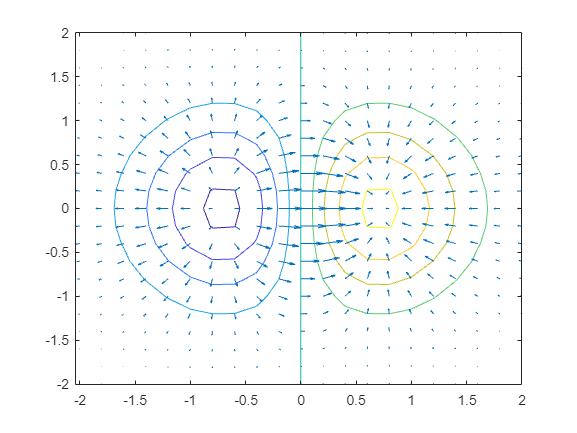

figure
contour(x,y,z)
hold on
quiver(x,y,px,py)
hold off

*Copyright 2012 The MathWorks, Inc.*

## 2. Aprenem... Fòrmules bàsiques.

### Exercici 1. 

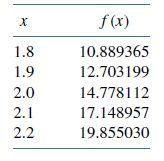

Calcular f'(2.0) con h=0.1 y h=02. Los datos son de f(x)=x*e^x, calcular los errores absolutos. Crear tabla para visualitzar error absoluto en las fórmulas usadas

clearvars
x=[1.8:0.1:2.2]; y=[x.*exp(x)]; 
disp([x;y]')

          1.8       10.889
          1.9       12.703
            2       14.778
          2.1       17.149
          2.2       19.855



%L'error es redueix per 2 ja que es h
% valor exacte
der=exp(2)+2.*exp(2);

% formula endavant h=0.2
der_2=((2.2).*exp(2.2)-2.*exp(2))/(0.2);

% formula endavant h=0.1
der_1=((2.1).*exp(2.1)-2.*exp(2))/(0.1);
% taula resultats
disp(array2table([0.2,der_2,abs(der_2-der);0.1,der_1,abs(der_1-der)],'VariableNames',{'h','aprox','error-abs'}));

     h     aprox     error-abs
    ___    ______    _________

    0.2    25.385     3.2174  
    0.1    23.708     1.5413  



%L'error es redueix per 4 ja que es h^2
% formula centrada h=0.2
der_2=((2.2).*exp(2.2)-1.8.*exp(1.8))/(0.4);

% formula centrada h=0.1
der_1=((2.1).*exp(2.1)-1.9.*exp(1.9))/(0.2);
% taula resultats
disp(array2table([0.2,der_2,abs(der_2-der);0.1,der_1,abs(der_1-der)],'VariableNames',{'h','aprox','error-abs'}));

     h     aprox     error-abs
    ___    ______    _________

    0.2    22.414     0.24699 
    0.1    22.229    0.061619 



### Exercici 2 

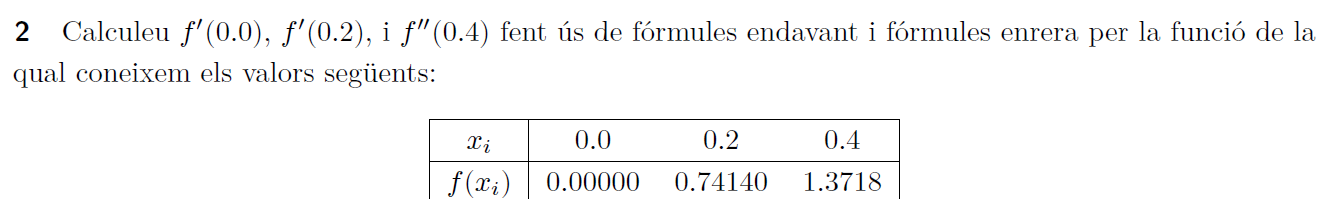

clearvars
x=[0 0.2 0.4]; y=[0 0.74140 1.3718]; 
disp([x;y]')

            0            0
          0.2       0.7414
          0.4       1.3718



% formula endavant h=0.2
h=0.2;
der=(y(2)-y(1))/h;
der=(y(3)-y(2))/h;
yp=diff(y)/h

yp =         3.707        3.152


% formula enrera h=0.2
fp_back=(y(2:3)-y(1:2))/h %da lo mimo obviamente

fp_back =         3.707        3.152


### Exercici 3

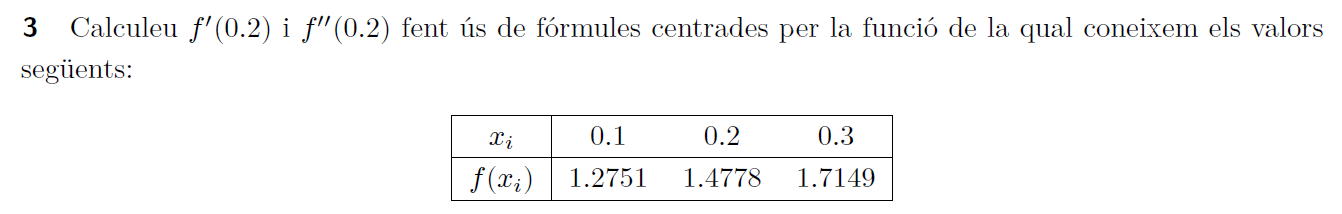

clearvars
x=[0.1, 0.2,0.3]; y=[1.2751 1.4778 1.7149]; 
disp([x;y]')

          0.1       1.2751
          0.2       1.4778
          0.3       1.7149



der_cent=(y(3)-y(1))/0.2

der_cent =         2.199


yp2=(y(3)-2*y(2)+y(1))/(0.1)^2

yp2 =          3.44


### **Exercici 4**

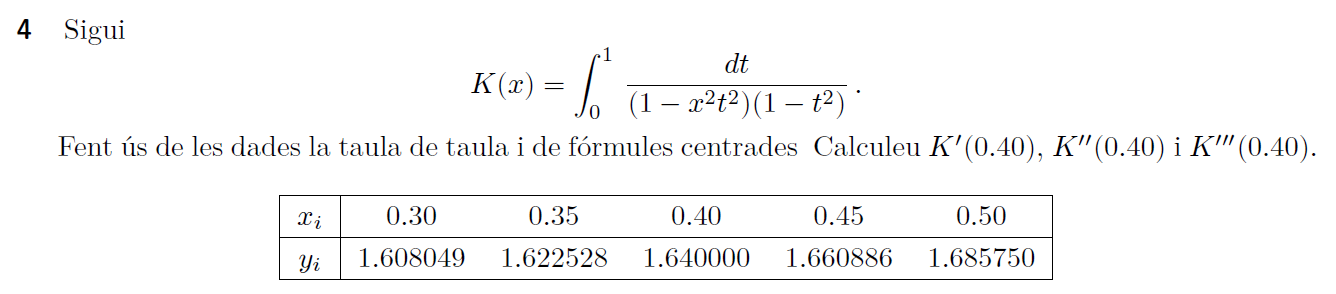

clearvars
x=[0.3:0.05:0.5];
x2=x .^2;
format longG
y = round(ellipke(x2),7,'significant');
T = array2table([x;y]',"VariableNames",{'x_i','y_i'}); disp(T)

    x_i       y_i   
    ____    ________

     0.3    1.608049
    0.35    1.622528
     0.4        1.64
    0.45    1.660886
     0.5     1.68575



## 3. Practiquem...  

### **Exercici 5  **O(h)

Se sabe que la derivada de $\ln(x)$ en $x=2$ tiene el valor de $f^{\prime}(2)=\frac 12$. Se pide:

a) Aproximar $f^{\prime}(2)$ mediante la fórmula $	\mathbf{F1}\::f^{\prime}(x_0)\approx\frac{f(x_0+h)-f(x_0)}{h}
$, per $h_k=5^{-k}$ para $k=1,2,3\dots, 15.$

clearvars
format shortG

k = 1:15;
h = 1./5.^(k);
f1 = (log(2+h)-log(2))./(h);
er = abs(f1-0.5);
ratio=(er(1:end-1)./er(2:end)) %error máquina es inversament proporcional a h, a h molt petits aumenta l'error

ratio =        4.7522       4.9475       4.9894       4.9979       4.9996       4.9999       5.0004       5.0154       4.9687       6.4267            1     0.018094       0.6874            1


disp(table(k',h',f1',er','VariableNames',{'k','h','fprime(2)','error absolut'}))

    k         h         fprime(2)    error absolut
    __    __________    _________    _____________

     1           0.2     0.47655        0.023449  
     2          0.04     0.49507       0.0049343  
     3         0.008       0.499      0.00099734  
     4        0.0016      0.4998      0.00019989  
     5       0.00032     0.49996      3.9996e-05  
     6       6.4e-05     0.49999      7.9998e-06  
     7      1.28e-05         0.5         1.6e-06  
     8      2.56e-06         0.5      3.1997e-07  
     9      5.12e-07         0.5      6.3797e-08  
    10     1.024e-07         0.5       1.284e-08  
    11     2.048e-08         0.5      1.9979e-09  
    12     4.096e-09         0.5      1.9979e-09  
    13     8.192e-10         0.5      1.1042e-07  
    14    1.6384e-10         0.5      1.6063e-07  
    15    3.2768e-11         0.5      1.6063e-0

b) Calculad el error absolut opara cada una de las aproximaciones obtenidas. Presentar los resultados en una tabla T2.  Representad el error en una gráfica, absicisas $k=1,2,3\dots, 15$ y ordenadas $log_{10}(error)$

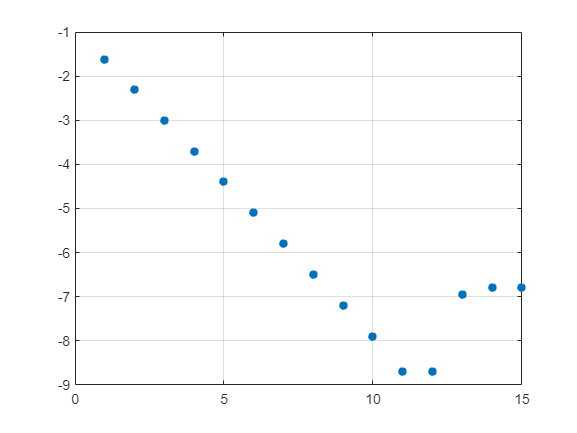

plot(k,log10(er),'*','LineWidth',2),grid

**c) **Observad la existencia de un h óptimo, a partir del cúal si se toman valores de $h$ más pequeños, los errores crecen. Cúal es el valor de h para la fórmula $\mathbf{F1}$?

**RESPUESTA:: **

### **Exercici 6  **O(h^2)

Repetir el ejercicio 5 usando la fórmula $\mathbf{F2}\::f^{\prime}(x_0)\approx\frac{f(x_0+h)-f(x_0-h)}{2h}.$

% Fórmula centrada
clearvars
f=@(x)log(x);


**b)** Calculad el error absoluto para cada una de las aproximaciones obtenidas. Presentar los resultados en una tabla.

Representad el error en una gráfica, abscisas $k=1,2,3\dots, 15$ y ordenadas $log_{10}(error)$

**c) **Observad la existencia de un h óptimo, a partir del cúal si se toman valores de $h$ más pequeños, los errores crecen. 

Cúal es el valor de h para la fórmula $\mathbf{F2}$?

**RESPUESTA:: **

## 4. Practiquem...  

### **Exercici 7  **O(h^2)

Se sabe que la derivada de $\ln(x)$ en $x=2$ tiene el valor de $f^{\prime}(2)=\frac 12$. Se pide:

a) Aproximar $f^{\prime}(2)$ mediante la fórmula $\mathbf{F2}\::f^{\prime}(x_0)\approx\frac{f(x_0+h)-f(x_0-h)}{2h},$ per $h_k=2^{-k}$ para $k=1,2,3\dots, 15.$

clearvars
format shortG
f=@(x)log(x); 
k = 1:5;

h = 1./2.^(k);
f1 = (log(2+h)-log(2-h))./(2*h);
er = abs(f1-0.5);
disp(table(k',h',f1',er','VariableNames',{'k','h','fprime(2)','error absolut'}))

    k       h       fprime(2)    error absolut
    _    _______    _________    _____________

    1        0.5     0.51083        0.010826  
    2       0.25     0.50263       0.0026289  
    3      0.125     0.50065      0.00065257  
    4     0.0625     0.50016      0.00016286  
    5    0.03125     0.50004      4.0696e-05  



b) Usad la técnica de Extrapolación de Richardson para obtener $f^{\prime}(2)$ con más decimales correctes. Calculad el error absolut opara cada una de las aproximaciones obtenidas. Presentar los resultados en una tabla T3. Representad el error en una gráfica, absicisas $k=1,2,3\dots, 15$ y ordenadas $log_{10}(error)$.

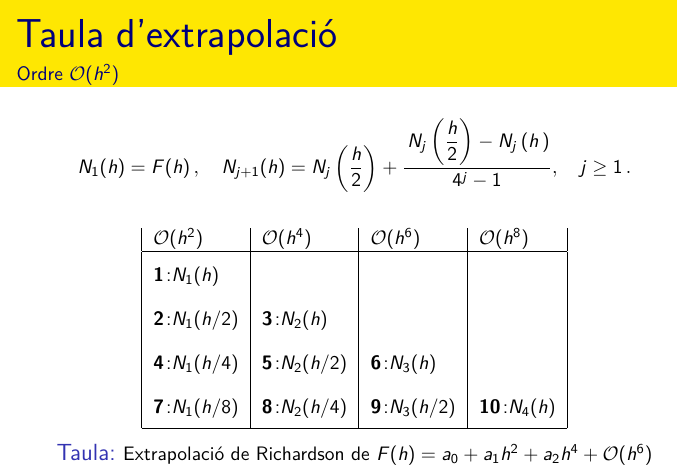

**Primera columna N_1**

N1 = f1'

N1 =       0.51083
      0.50263
      0.50065
      0.50016
      0.50004


m=length(k)

m =      5


**Primera extrapolació, columna N_2**

N2(2:m) =(4*N1(2:m)-N1(1:m-1))/3;
[k',N2', abs(N2'-0.5)]

ans =             1            0          0.5
            2       0.4999    0.0001034
            3      0.49999   6.1898e-06
            4          0.5    3.828e-07
            5          0.5   2.3863e-08


**Segona extrapolació, columna N_3**

**Tercera extrapolació, columna N_4**

c) Representad las cifras decimales correctas en una gráfica con $k=1,2,3\dots, 15$ en el eje de abscisas.

## 5. AutoAvaluació 

### Exercici 8

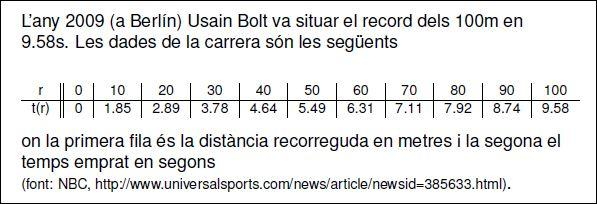

Calculeu una aproximació de la velocitat i l'acceleració en la carrera. Feu una representació gràfica 

dels valors obtinguts

format short g
r=0:10:100;
t=[0 1.85 2.89 3.78 4.64 5.49 6.31 7.11 7.92 8.74 9.58];
disp([r;t]')

            0            0
           10         1.85
           20         2.89
           30         3.78
           40         4.64
           50         5.49
           60         6.31
           70         7.11
           80         7.92
           90         8.74
          100         9.58



**Velocitat i acceleració**

**Gràfics**

### Exercici 9.  O(h)

Se sabe que la derivada de $\ln(x)$ en $x=2$ tiene el valor de $f^{\prime}(2)=\frac 12$. Se pide:

a) Aproximar $f^{\prime}(2)$ mediante la fórmula $	\mathbf{F1}\::f^{\prime}(x_0)\approx\frac{f(x_0+h)-f(x_0)}{h}
$, per $h_k=2^{-k}$ para $k=1,2,3\dots, 15.$

clearvars; 
format short g


b) Usad la técnica de Extrapolación de Richardson para obtener $f^{\prime}(2)$ con más decimales correctes. Calculad el error absoluto  para cada una de las aproximaciones obtenidas. Presentar los resultados en una tabla T. Representad el error en una gráfica, absicisas $k=1,2,3\dots, 15$ y ordenadas $log_{10}(error)$.

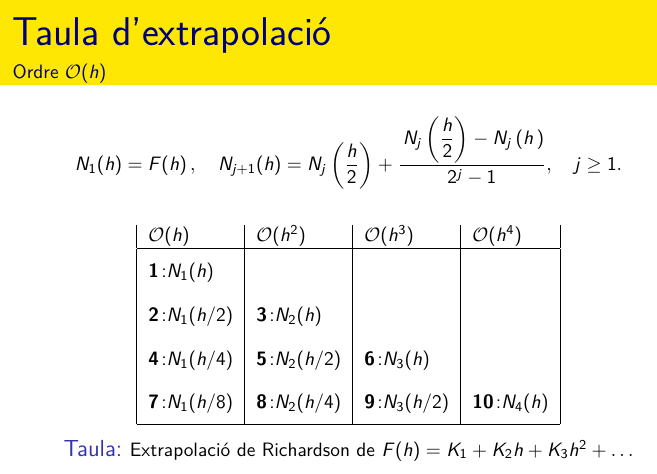

**Primera columna N_1**

**Primera extrapolació, columna N_2**

**Segona extrapolació, columna N_3**

**Tercera extrapolació, columna N_4**

c) Respresentad las cifras decimales correctas en una gráfica con $k=1,2,3\dots, 15$ en el eje de abscisas.

`Document preparat per Mª Àngela Grau Gotés (prof. responsable CN)`